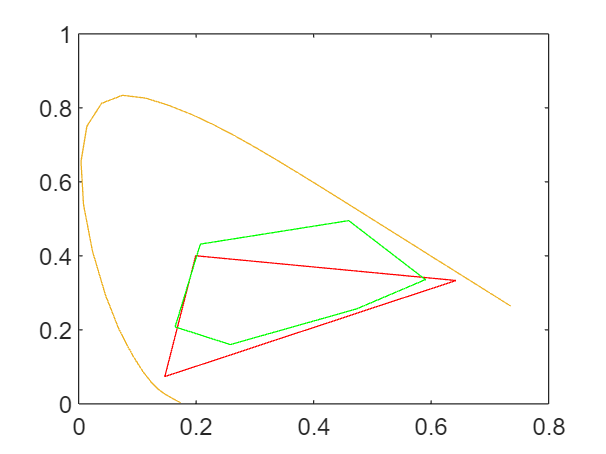

%1.1 
clear
load("Dell.mat")
load("Inkjet.mat")

plot_chrom(XYZdell, 'r')
plot_chrom(XYZinkjet, 'g')

1.1 We can clearly see that the dell computer screen is better at reproducing red and blue because it covers more of the red spectrum [0.6, 0.8]. Inkjet is better as reproducing yellow and green. Dell is RGB and Inkjet not CMYKRG. Dell triangle, Inkjet not triangle.

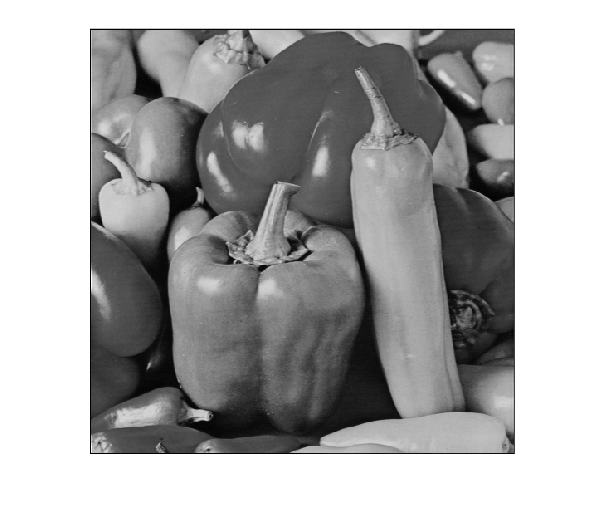

%2.1.1

imgPepperG = im2double(imread("peppers_gray.tif"));
imshow(imgPepperG);


peppaGnearest = imresize(imresize(imgPepperG,0.25,'nearest'),4,'nearest');
peppaGbilinear = imresize(imresize(imgPepperG,0.25,'bilinear'),4,'bilinear');
peppaGbicubic = imresize(imresize(imgPepperG,0.25,'bicubic'),4,'bicubic');

snrner = mysnr(imgPepperG, imgPepperG-peppaGnearest)

snrner = 17.0956

snrbil = mysnr(imgPepperG, imgPepperG-peppaGbilinear)

snrbil = 18.8922

snrbic = mysnr(imgPepperG, imgPepperG-peppaGbicubic)

snrbic = 19.8538


msener = immse(imgPepperG, peppaGnearest)

msener = 0.0043

msebil = immse(imgPepperG, peppaGbilinear)

msebil = 0.0028

msebic = immse(imgPepperG, peppaGbicubic)

msebic = 0.0023

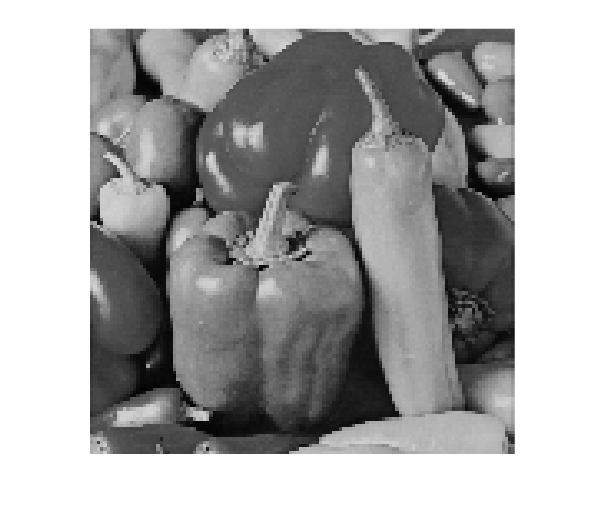


imshow(peppaGnearest)

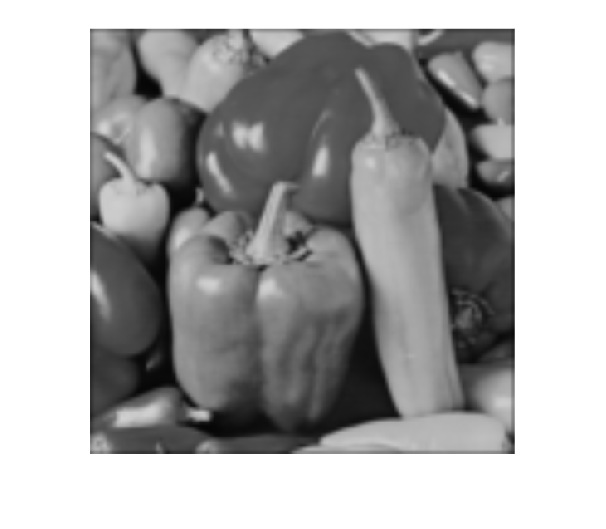

imshow(peppaGbilinear)

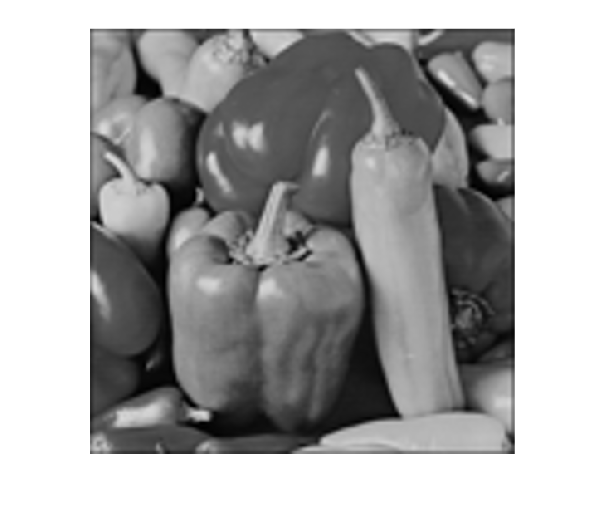

imshow(peppaGbicubic)

Bicubic looks best and the snr value is higher, mse is lower. Max likes bilinear but depends on use case.

%2.1.2

i = im2double(imgPepperG);
imgThresh = im2double(i >= .5);
imgDither = im2double(dither(i));

snrnth = mysnr(i, i-imgThresh)

snrnth = 2.9721

snrdit = mysnr(i, i-imgDither)

snrdit = 0.4112



msenth = immse(i, imgThresh)

msenth = 0.1111

msedit = immse(i, imgDither)

msedit = 0.2004

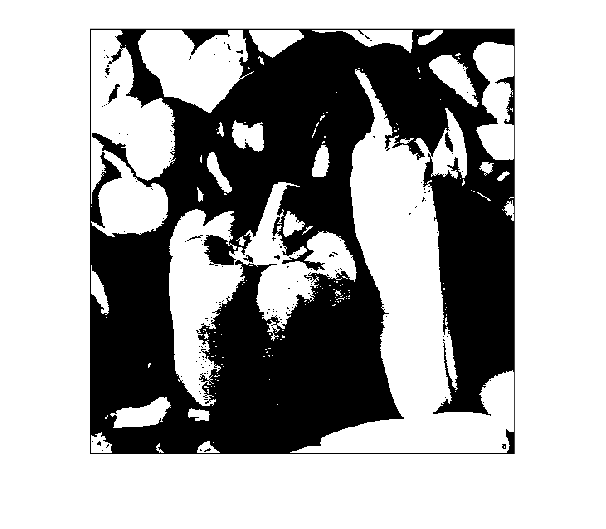



imshow(imgThresh)

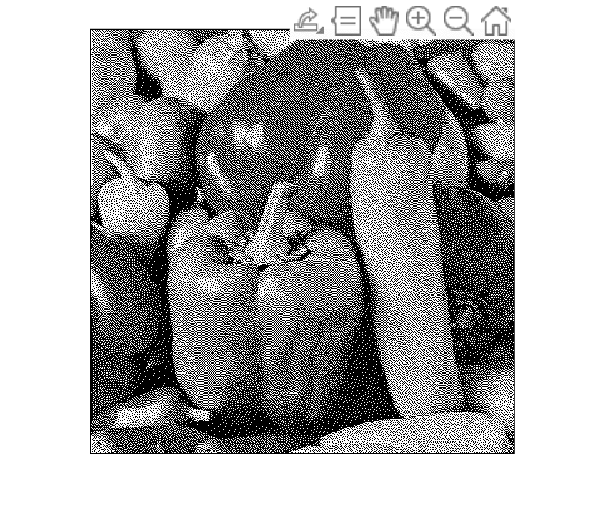

imshow(imgDither)

2.1.2 Dither is better looking than thresholding. Although, mean square distance is lower for threshold and snr is higher although it looks worse. 

%2.2
peppaC = imread("peppers_color.tif");
peppaCLab = rgb2lab(peppaC);
%deltaE()
peppaCThresh = im2double(im2double(peppaC) >= 0.5);

peppaCdither(:,:,1) = dither(peppaC(:,:,1)); 
peppaCdither(:,:,2) = dither(peppaC(:,:,2)); 
peppaCdither(:,:,3) = dither(peppaC(:,:,3)); 

peppaCdither = im2double(peppaCdither);
ditherLab = rgb2lab(peppaCdither);
threshLab = rgb2lab(peppaCThresh);
ditherdeltaE = zeros(512,512);
threshdeltaE = zeros(512,512);
for i = 1:512
    for j = 1:512
        ditherdeltaE(i,j) = ditherdeltaE(i,j) + sqrt((ditherLab(i,j,1) - peppaCLab(i,j,1))^2 + (ditherLab(i,j,2) - peppaCLab(i,j,2))^2 + (ditherLab(i,j,3) - peppaCLab(i,j,3))^2);
        threshdeltaE(i,j) = threshdeltaE(i,j) + sqrt((threshLab(i,j,1) - peppaCLab(i,j,1))^2 + (threshLab(i,j,2) - peppaCLab(i,j,2))^2 + (threshLab(i,j,3) - peppaCLab(i,j,3))^2);
    end
end

maxDeltaEdither = max(max(ditherdeltaE))

maxDeltaEdither = 203.6272

meanDeltaEdither = mean(mean(ditherdeltaE))

meanDeltaEdither = 72.8423

maxDeltaEthresh = max(max(threshdeltaE))

maxDeltaEthresh = 120.1919

meanDeltaEthresh = mean(mean(threshdeltaE))

meanDeltaEthresh = 50.1577

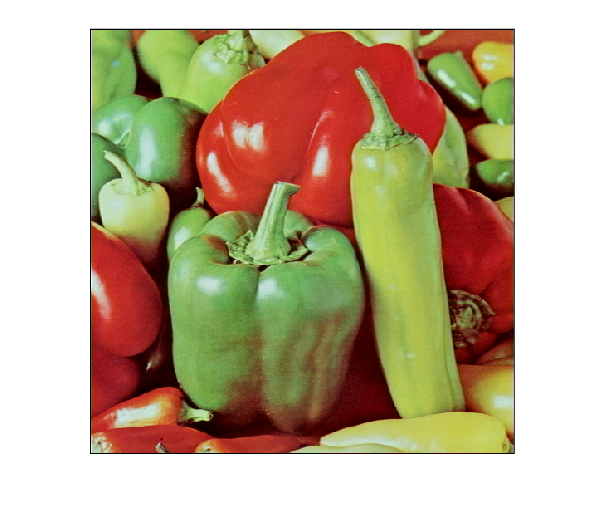


imshow(peppaC)

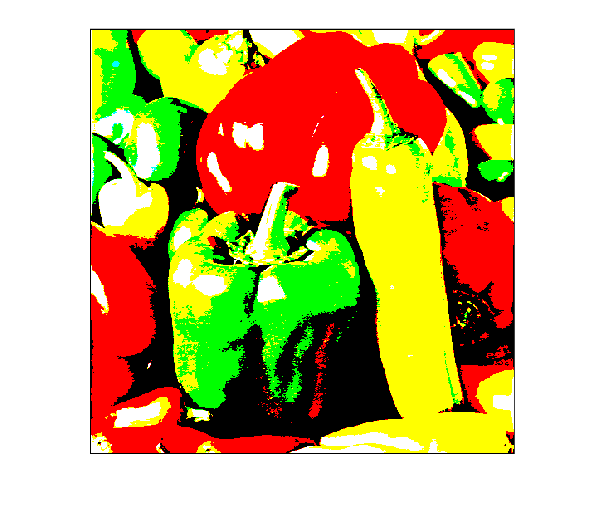

imshow(peppaCThresh)

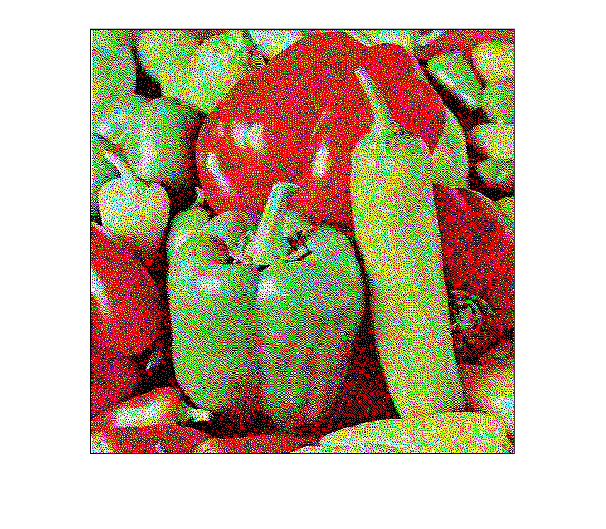

imshow(peppaCdither)

2.2 Dither is closer to the original and is reflected in the DeltaE results. Thresholding color values gives very strong colors which do not look good compared to the original. 

%3.1
peppaG = im2double(imgPepperG)

peppaG =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7451    0.5843    0.6078    0.6118    0.6353    0.6510    0.6588    0.6588    0.6588    0.6588    0.6667    0.6745    0.6824    0.6784    0.6784    0.6824    0.6784    0.6706    0.6549    0.6314    0.6235    0.6275    0.6039    0.5804    0.5725    0.5569    0.5490    0.5333    0.5373    0.5255    0.5098    0.5098    0.5176    0.5176    0.5098    0.5176    0.5216    0.5020    0.5059    0.5020    0.4824    0.4627    0.4275    0.3961    0.3608    0.3294    0.2902    0.2549



snr_filter(peppaG, peppaG - imgThresh)

ans = 3.3488

snr_filter(peppaG, peppaG - imgDither)

ans = 13.3230


imshow(imgThresh)

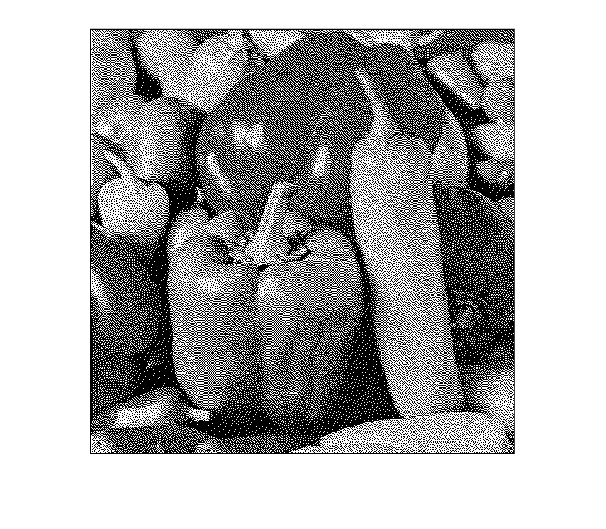

imshow(imgDither)

Dither looks better and gives a better result for snr. 

%3.2 
% 1/188 * 406.4

f=MFTsp(15,0.0847,500);
peppaC = im2double(peppaC)

peppaC = peppaC(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    


peppaCconv(:,:,1)=conv2(peppaC(:,:,1),f,'same');
peppaCconv(:,:,2)=conv2(peppaC(:,:,2),f,'same');
peppaCconv(:,:,3)=conv2(peppaC(:,:,3),f,'same');
% Ögats filter är applicerat till signalen (originalbilden)

peppaCditherConv(:,:,1)=conv2(peppaCdither(:,:,1),f,'same');
peppaCditherConv(:,:,1) = (peppaCditherConv(:,:,1) >0).*peppaCditherConv(:,:,1);
peppaCditherConv(:,:,2)=conv2(peppaCdither(:,:,2),f,'same');
peppaCditherConv(:,:,2) = (peppaCditherConv(:,:,2) >0).*peppaCditherConv(:,:,2);
peppaCditherConv(:,:,3)=conv2(peppaCdither(:,:,3),f,'same');
peppaCditherConv(:,:,3) = (peppaCditherConv(:,:,3) >0).*peppaCditherConv(:,:,3);

peppaCThreshConv(:,:,1)=conv2(peppaCThresh(:,:,1),f,'same');
peppaCThreshConv(:,:,1) = (peppaCThreshConv(:,:,1) >0).*peppaCThreshConv(:,:,1);
peppaCThreshConv(:,:,2)=conv2(peppaCThresh(:,:,2),f,'same');
peppaCThreshConv(:,:,2) = (peppaCThreshConv(:,:,2) >0).*peppaCThreshConv(:,:,2);
peppaCThreshConv(:,:,3)=conv2(peppaCThresh(:,:,3),f,'same');
peppaCThreshConv(:,:,3) = (peppaCThreshConv(:,:,3) >0).*peppaCThreshConv(:,:,3);

peppaCconvLab = rgb2lab(peppaCconv);
peppaCditherConvLab = rgb2lab(peppaCditherConv);
peppaCThreshConvLab = rgb2lab(peppaCThreshConv);

ditherdeltaE = zeros(512,512);
threshdeltaE = zeros(512,512);
for i = 1:512
    for j = 1:512
        ditherdeltaE(i,j) = ditherdeltaE(i,j) + sqrt((peppaCditherConvLab(i,j,1) - peppaCconvLab(i,j,1))^2 + (peppaCditherConvLab(i,j,2) - peppaCconvLab(i,j,2))^2 + (peppaCditherConvLab(i,j,3) - peppaCconvLab(i,j,3))^2);
        threshdeltaE(i,j) = threshdeltaE(i,j) + sqrt((peppaCThreshConvLab(i,j,1) - peppaCconvLab(i,j,1))^2 + (peppaCThreshConvLab(i,j,2) - peppaCconvLab(i,j,2))^2 + (peppaCThreshConvLab(i,j,3) - peppaCconvLab(i,j,3))^2);
    end
end

maxDeltaEdither = max(max(ditherdeltaE))

maxDeltaEdither = 83.1636

meanDeltaEdither = mean(mean(ditherdeltaE))

meanDeltaEdither = 20.1669

maxDeltaEthresh = max(max(threshdeltaE))

maxDeltaEthresh = 105.7033

meanDeltaEthresh = mean(mean(threshdeltaE))

meanDeltaEthresh = 48.0322


imshow(peppaC)

imshow(peppaCThresh)

imshow(peppaCdither)

3.2 Yes the dither has better mean and max values than threshold.

%4.1 

PPI = 188.66;
d = 20; %50 cm

SPD = PPI * d * tan(pi/180)

SPD = 65.8615


CIED65samp = [95.05, 100, 108.9];

peppaCnearest = imresize(imresize(peppaC,0.25,'nearest'),4,'nearest');
peppaCbilinear = imresize(imresize(peppaC,0.25,'bilinear'),4,'bilinear');
peppaCbicubic = imresize(imresize(peppaC,0.25,'bicubic'),4,'bicubic');
peppaCxyz = rgb2xyz(peppaC);
peppaCnearestxyz = rgb2xyz(peppaCnearest);
peppaCbilinearxyz = rgb2xyz(peppaCbilinear);
peppaCbicubicxyz = rgb2xyz(peppaCbicubic);

peppaCNeres = scielab(SPD,peppaCxyz,peppaCnearestxyz, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


peppaCBilres = scielab(SPD,peppaCxyz,peppaCbilinearxyz, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


peppaCBicres = scielab(SPD,peppaCxyz,peppaCbicubicxyz, CIED65samp, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...




mean(mean(peppaCNeres))

ans = 0.1663

mean(mean(peppaCBilres))

ans = 0.1774

mean(mean(peppaCBicres))

ans = 0.1060

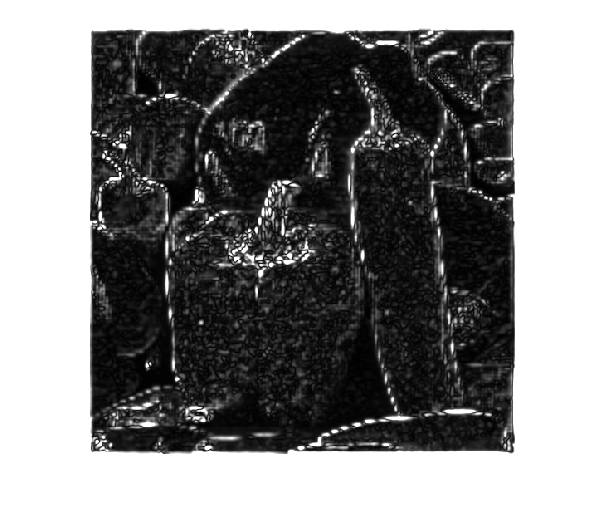


imshow(peppaCNeres)

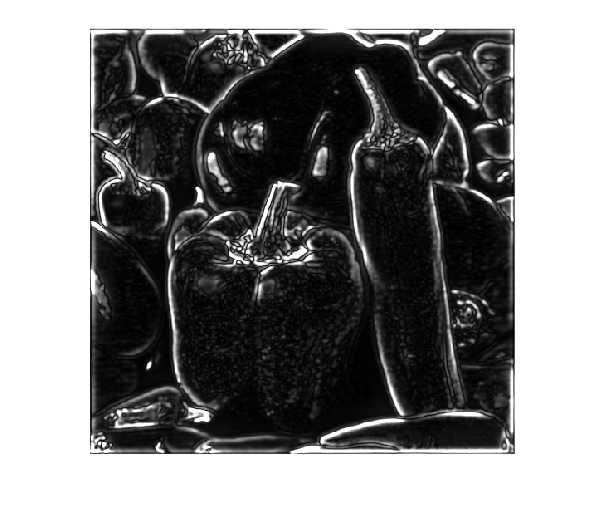

imshow(peppaCBilres)

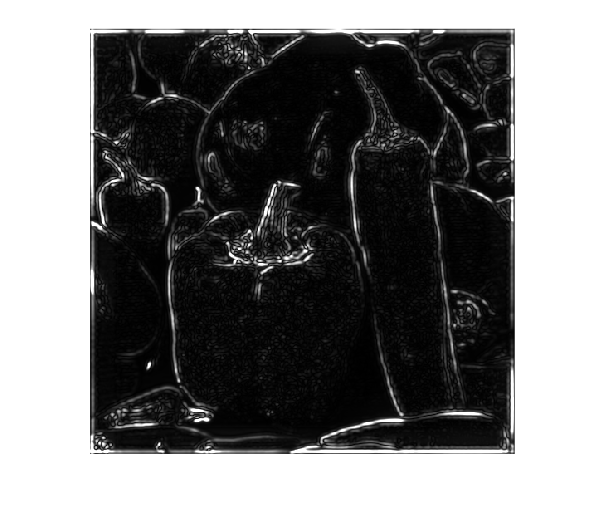

imshow(peppaCBicres)

4.1 Bicubic is the winner quality-wise. 

%4.2
load("colorhalftones.mat")

c1xyz = rgb2xyz(c1);
c2xyz = rgb2xyz(c2);
c1lab = scielab(SPD, c1xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c2lab = scielab(SPD, c2xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


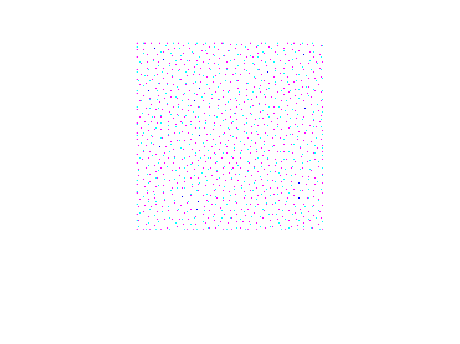

imshow(c1)

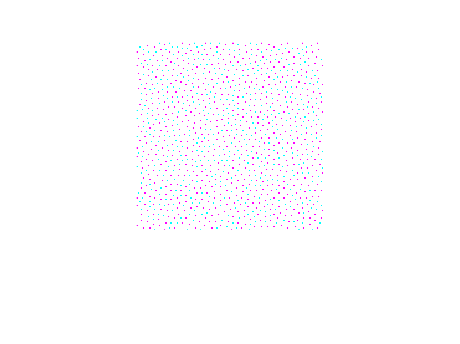

imshow(c2)


c1sd = std2(c1lab(:,:,1));
c1sd = c1sd + std2(c1lab(:,:,2));
c1sd = c1sd + std2(c1lab(:,:,3))

c1sd = 0.0191


c2sd = std2(c2lab(:,:,1));
c2sd = c2sd + std2(c2lab(:,:,2));
c2sd = c2sd + std2(c2lab(:,:,3))

c2sd = 0.0145

Very difficult to tell a differance.

c3xyz = rgb2xyz(c3);
c4xyz = rgb2xyz(c4);
c5xyz = rgb2xyz(c5);
c3lab = scielab(SPD, c3xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c4lab = scielab(SPD, c4xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c5lab = scielab(SPD, c5xyz);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


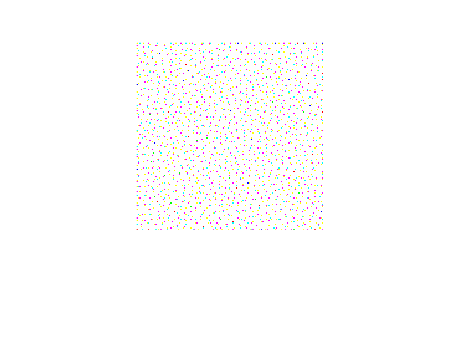


imshow(c3)

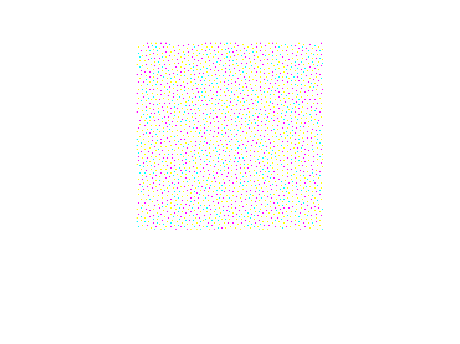

imshow(c4)

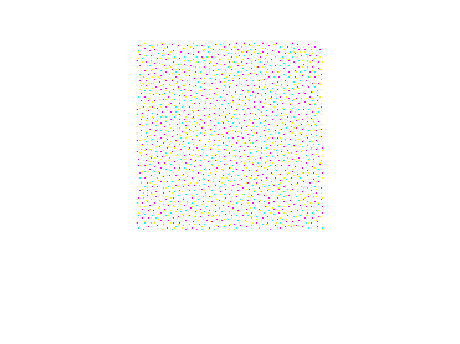

imshow(c5)


c3sd = std2(c3lab(:,:,1));
c3sd = c3sd + std2(c3lab(:,:,2));
c3sd = c3sd + std2(c3lab(:,:,3))

c3sd = 0.0196


c4sd = std2(c4lab(:,:,1));
c4sd = c4sd + std2(c4lab(:,:,2));
c4sd = c4sd + std2(c4lab(:,:,3))

c4sd = 0.0214


c5sd = std2(c5lab(:,:,1));
c5sd = c5sd + std2(c5lab(:,:,2));
c5sd = c5sd + std2(c5lab(:,:,3))

c5sd = 0.0161

C4 is halftoned dependently, C3 is halftoned independently and C5 is mixed.

%5.1
peppaGdistort1 = peppaG

peppaGdistort1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7451    0.5843    0.6078    0.6118    0.6353    0.6510    0.6588    0.6588    0.6588    0.6588    0.6667    0.6745    0.6824    0.6784    0.6784    0.6824    0.6784    0.6706    0.6549    0.6314    0.6235    0.6275    0.6039    0.5804    0.5725    0.5569    0.5490    0.5333    0.5373    0.5255    0.5098    0.5098    0.5176    0.5176    0.5098    0.5176    0.5216    0.5020    0.5059    0.5020    0.4824    0.4627    0.4275    0.3961    0.3608    0.3294    0.2902  

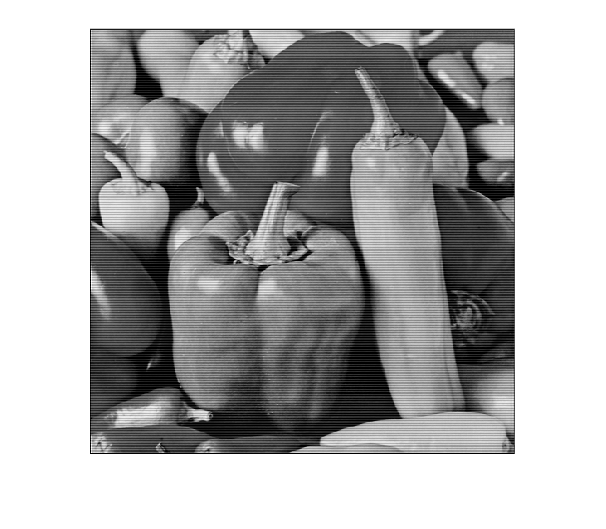


for i = 1:512
    for j = 1:512
        if mod(i,2) == 0
            peppaGdistort1(i,j) =  peppaGdistort1(i,j) - .1;
        else 
            peppaGdistort1(i,j) =  peppaGdistort1(i,j) + .1;
        end
    end
end

peppaGdistort2 = peppaG;

for i = 1:512
    for j = 1:512
        if i > 512/2
            peppaGdistort2(i,j) =  peppaGdistort2(i,j) - .1;
        else 
            peppaGdistort2(i,j) =  peppaGdistort2(i,j) + .1;
        end
    end
end

imshow(peppaGdistort1)

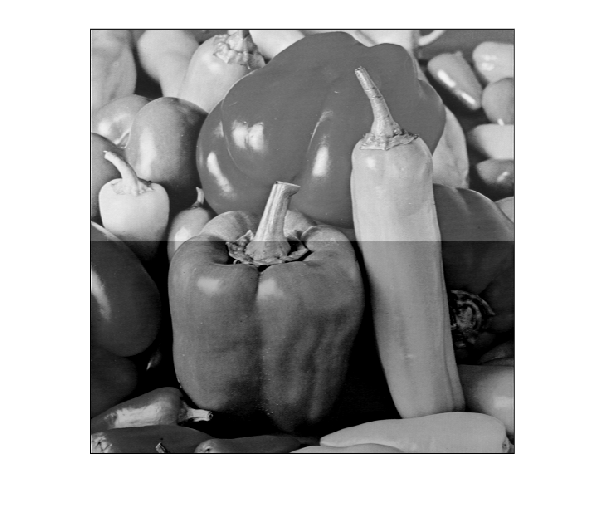

imshow(peppaGdistort2)


[distort1val, distort1map] = ssim(peppaG, peppaGdistort1)

distort1val = 0.2435

distort1map =     0.8489    0.9115    0.9281    0.9317    0.9332    0.9354    0.9374    0.9387    0.9393    0.9396    0.9401    0.9409    0.9419    0.9427    0.9431    0.9431    0.9426    0.9417    0.9402    0.9379    0.9351    0.9321    0.9291    0.9260    0.9224    0.9186    0.9148    0.9113    0.9083    0.9059    0.9040    0.9027    0.9019    0.9015    0.9009    0.9002    0.8990    0.8972    0.8949    0.8921    0.8885    0.8834    0.8751    0.8617    0.8413    0.8122    0.7735    0.7286    0.6929    0.6875
    0.9361    0.9510    0.9490    0.9433    0.9411    0.9422    0.9438    0.9448    0.9453    0.9456    0.9461    0.9468    0.9477    0.9484    0.9488    0.9487    0.9482    0.9472    0.9458    0.9437    0.9410    0.9380    0.9351    0.9322    0.9291    0.9256    0.9221    0.9188    0.9161    0.9140    0.9126    0.9117    0.9111    0.9105    0.9098    0.9087    0.9072    0.9051    0.9026    0.8999    0.8968    0.8927    0.8864    0.8760    0.8593    0.8349    0.8012    0.7595    0

[distort2val, distort2map] = ssim(peppaG, peppaGdistort2)

distort2val = 0.8528

distort2map =     0.7821    0.8873    0.9229    0.9342    0.9380    0.9402    0.9418    0.9428    0.9432    0.9435    0.9439    0.9445    0.9452    0.9458    0.9461    0.9461    0.9458    0.9451    0.9439    0.9422    0.9401    0.9380    0.9359    0.9337    0.9312    0.9286    0.9261    0.9238    0.9219    0.9203    0.9191    0.9181    0.9176    0.9173    0.9170    0.9166    0.9159    0.9149    0.9135    0.9117    0.9094    0.9060    0.9005    0.8922    0.8803    0.8647    0.8458    0.8265    0.8132    0.8119
    0.8938    0.9517    0.9686    0.9737    0.9754    0.9763    0.9770    0.9774    0.9775    0.9776    0.9778    0.9781    0.9784    0.9787    0.9788    0.9787    0.9785    0.9782    0.9777    0.9769    0.9760    0.9750    0.9741    0.9731    0.9721    0.9709    0.9698    0.9688    0.9679    0.9673    0.9667    0.9664    0.9662    0.9660    0.9658    0.9655    0.9652    0.9646    0.9639    0.9630    0.9619    0.9604    0.9580    0.9542    0.9486    0.9409    0.9311    0.9205    0

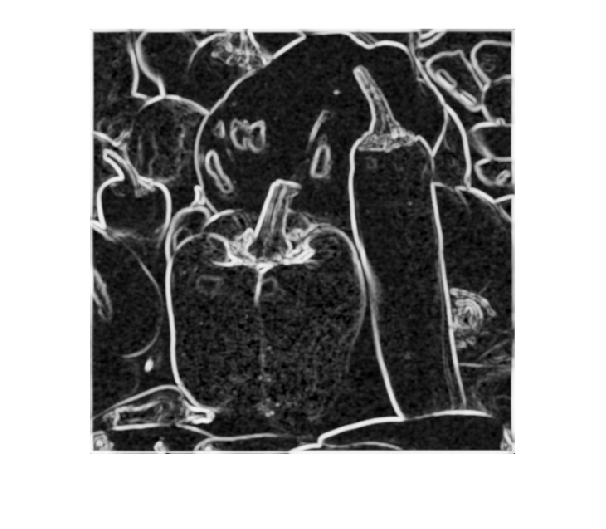

imshow(distort1map)

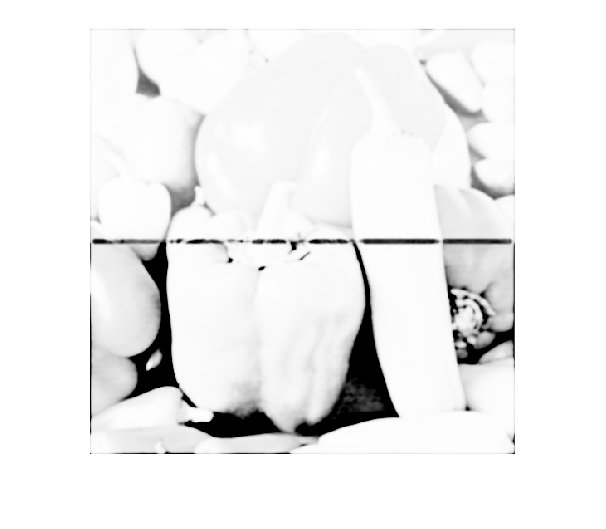

imshow(distort2map)

 5. The first one is less distracting but has a lower value. Max does not think this he likes the second one best because it is overall cleaner. 

%b

dist1=peppaG+0.2*(rand(size(peppaG))-0.5);
[dist1val, dist1map] = ssim(peppaG, dist1)

dist1val = 0.4335

dist1map =     0.9149    0.9643    0.9735    0.9770    0.9788    0.9793    0.9785    0.9785    0.9781    0.9786    0.9823    0.9861    0.9878    0.9882    0.9886    0.9885    0.9888    0.9899    0.9893    0.9875    0.9865    0.9858    0.9842    0.9820    0.9797    0.9782    0.9785    0.9798    0.9804    0.9799    0.9790    0.9785    0.9794    0.9801    0.9795    0.9775    0.9738    0.9695    0.9675    0.9699    0.9734    0.9735    0.9695    0.9593    0.9344    0.9065    0.8987    0.9038    0.9144    0.9228
    0.9640    0.9791    0.9819    0.9822    0.9811    0.9798    0.9794    0.9792    0.9785    0.9788    0.9814    0.9844    0.9859    0.9868    0.9878    0.9890    0.9897    0.9895    0.9888    0.9879    0.9866    0.9846    0.9821    0.9801    0.9790    0.9783    0.9780    0.9784    0.9782    0.9772    0.9767    0.9773    0.9783    0.9787    0.9785    0.9780    0.9758    0.9716    0.9693    0.9710    0.9740    0.9742    0.9703    0.9635    0.9552    0.9452    0.9356    0.9287    0.92

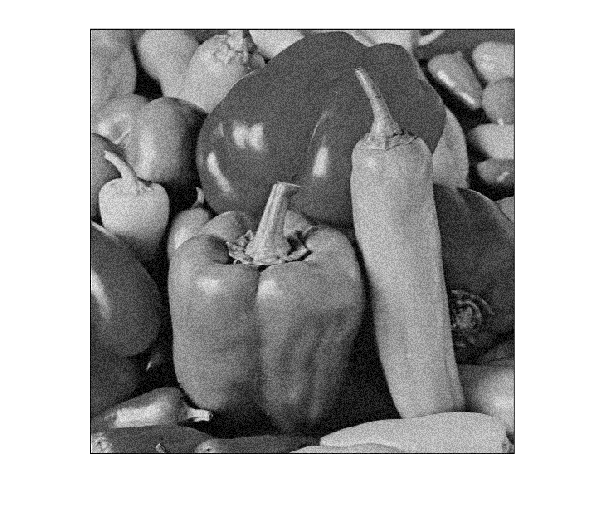


imshow(dist1);

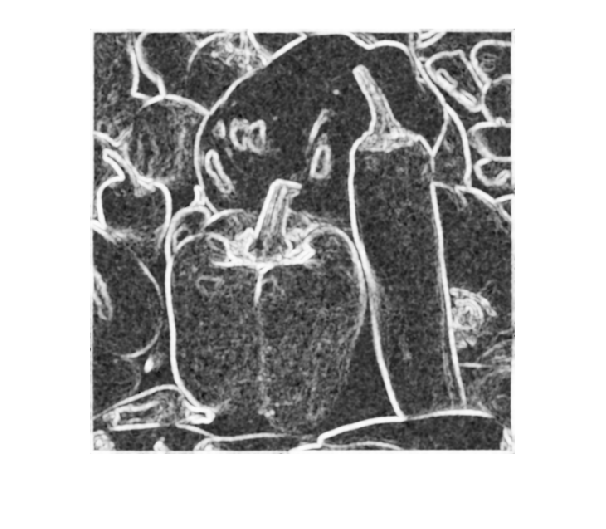

imshow(dist1map);


 f=fspecial('gauss',21,10);
 dist2 = imfilter(peppaG, f);
 [dist2val, dist2map] = ssim(peppaG, dist2)

dist2val = 0.6773

dist2map =     0.1160    0.1321    0.1303    0.1311    0.1374    0.1437    0.1484    0.1526    0.1571    0.1616    0.1652    0.1671    0.1673    0.1668    0.1663    0.1659    0.1658    0.1661    0.1671    0.1687    0.1703    0.1715    0.1726    0.1739    0.1754    0.1767    0.1774    0.1775    0.1772    0.1766    0.1759    0.1749    0.1732    0.1710    0.1687    0.1664    0.1643    0.1625    0.1610    0.1598    0.1594    0.1607    0.1642    0.1702    0.1783    0.1879    0.1983    0.2080    0.2134    0.2109
    0.1284    0.1308    0.1294    0.1356    0.1477    0.1587    0.1670    0.1750    0.1838    0.1929    0.2002    0.2039    0.2042    0.2028    0.2014    0.2004    0.1999    0.2001    0.2016    0.2042    0.2072    0.2096    0.2117    0.2143    0.2173    0.2200    0.2217    0.2224    0.2220    0.2211    0.2197    0.2175    0.2143    0.2104    0.2063    0.2022    0.1984    0.1951    0.1922    0.1895    0.1878    0.1886    0.1935    0.2032    0.2176    0.2361    0.2575    0.2785    0.29

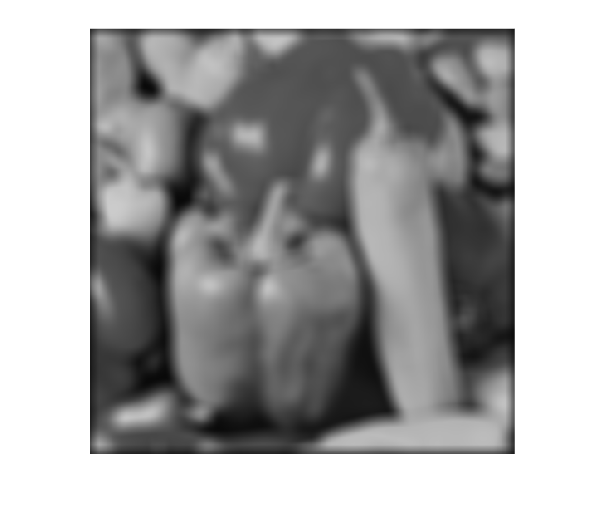


  imshow(dist2)

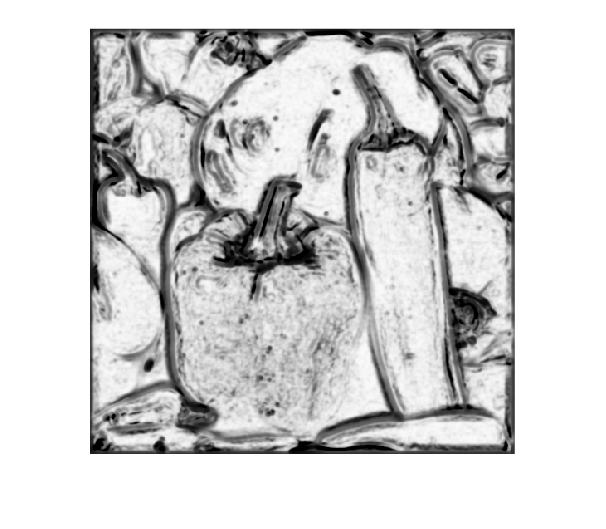

imshow(dist2map)